close all; clc; clear all;

random_load_power_cv = 0.1;
noise_v_sd = 0;
noise_i_sd = 0;

mpc = loadcase('case57');
n = size(mpc.bus, 1);
Y = full(makeYbus(mpc));
is_laplacian(Y)

ans = logical
   1


bus_voltage = load(sprintf('save_%d_%d.mat', n, random_load_power_cv)).bus_voltage;
ev = normrnd(0, noise_v_sd, size(bus_voltage));
ei = normrnd(0, noise_i_sd, size(bus_voltage));

bus_current = Y * bus_voltage + ei;
bus_voltage = bus_voltage + ev;

Y_hat_ols = conj(bus_voltage' \ bus_current');

Froebius norm for OLS is 260.8782
Max norm for OLS is 100.2015


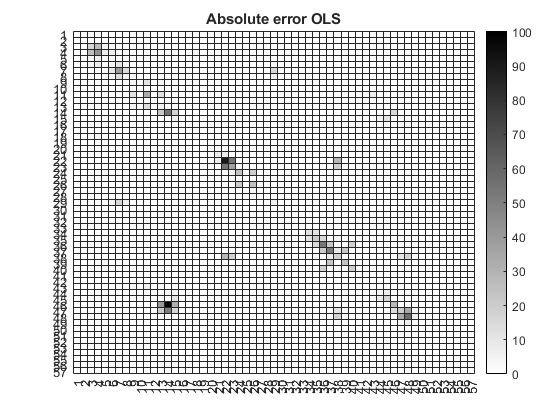

[ols_froeb_error, ols_max_error, chart] = error_metrics(Y, Y_hat_ols, 'OLS');

matlab_rank = 42

r = 1

Froebius norm for Y11 OLS is 318.5399
Max norm for Y11 OLS is 90.7722


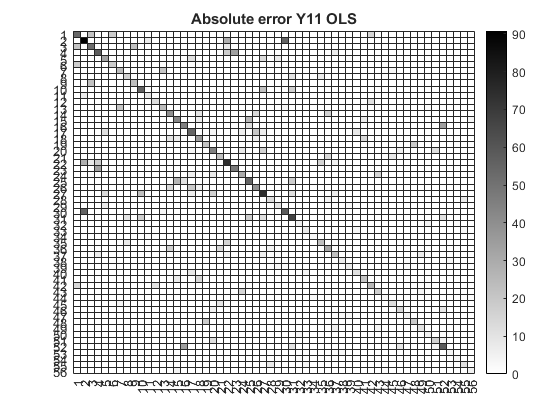

Froebius norm for Y22 OLS is 27.2446
Max norm for Y22 OLS is 27.2446


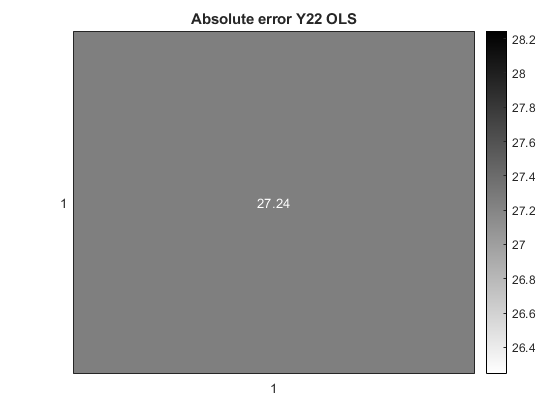

Froebius norm for OLS is 321.0222
Max norm for OLS is 90.7722


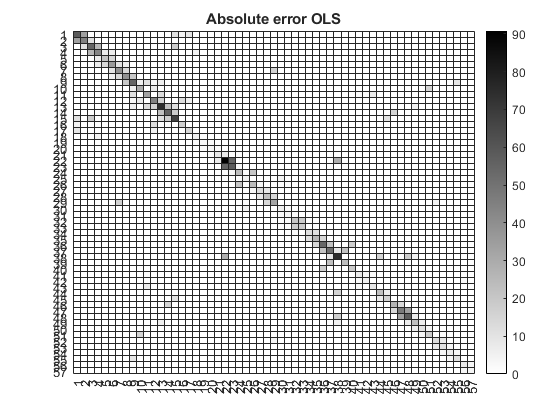

r = 4

Froebius norm for Y11 OLS is 319.871
Max norm for Y11 OLS is 90.7722


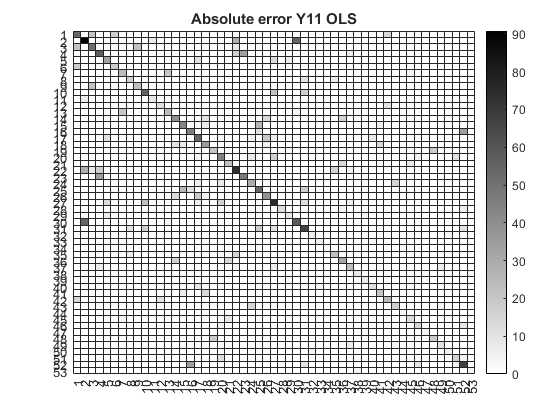

Froebius norm for Y22 OLS is 29.5759
Max norm for Y22 OLS is 27.1692


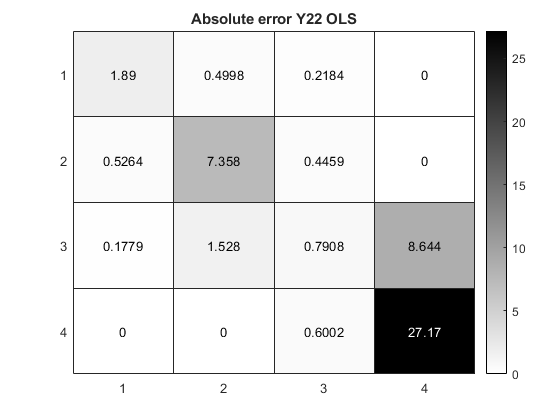

Froebius norm for OLS is 323.0836
Max norm for OLS is 90.7722


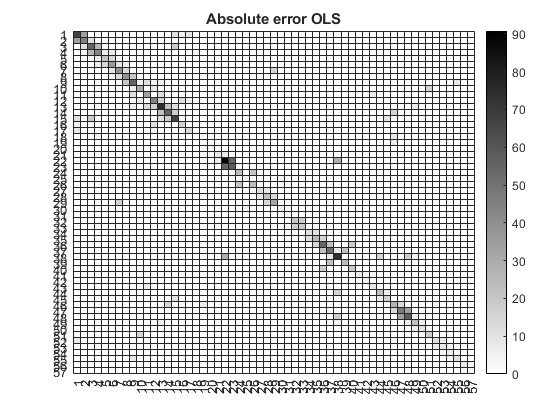

r = 7

Froebius norm for Y11 OLS is 309.0335
Max norm for Y11 OLS is 90.7722


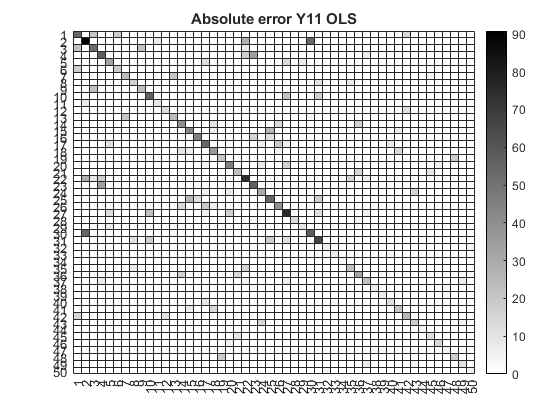

Froebius norm for Y22 OLS is 49.5601
Max norm for Y22 OLS is 39.111


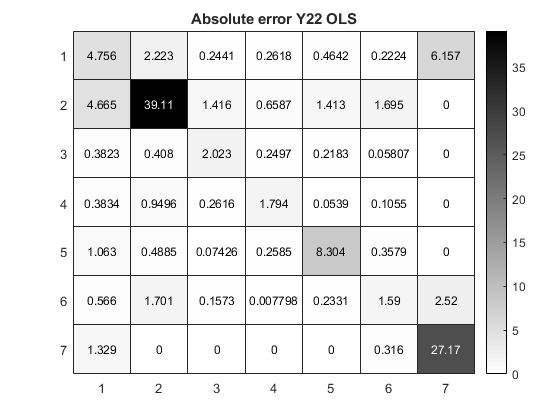

Froebius norm for OLS is 320.1274
Max norm for OLS is 90.7722


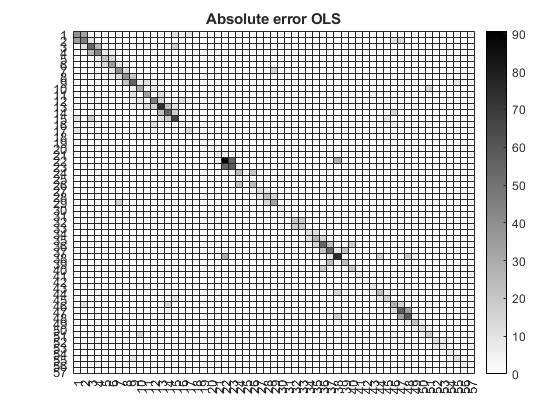

r = 10

Froebius norm for Y11 OLS is 306.2727
Max norm for Y11 OLS is 90.7722


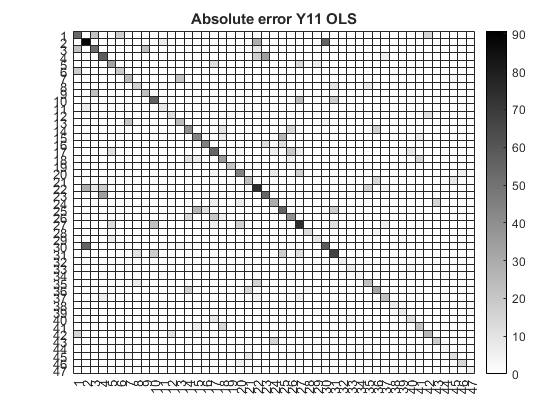

Froebius norm for Y22 OLS is 53.4787
Max norm for Y22 OLS is 39.4702


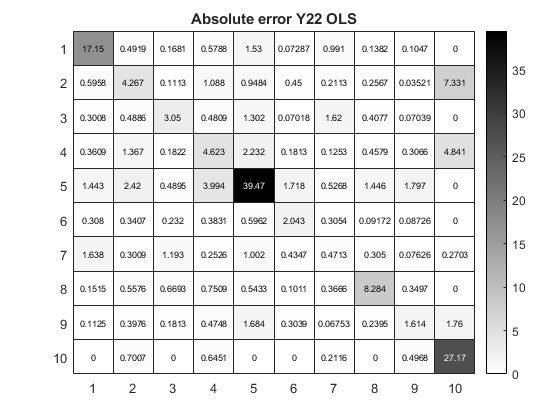

Froebius norm for OLS is 320.7239
Max norm for OLS is 90.7722


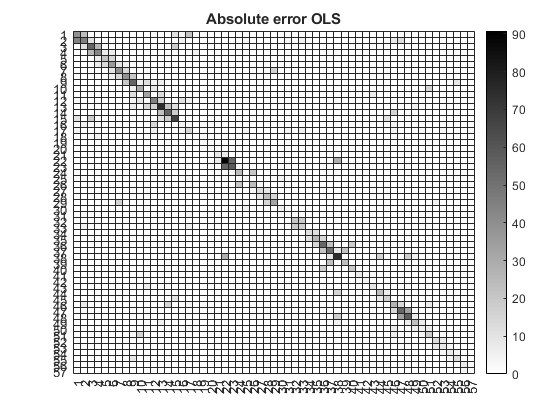

r = 13

Froebius norm for Y11 OLS is 305.0046
Max norm for Y11 OLS is 90.7722


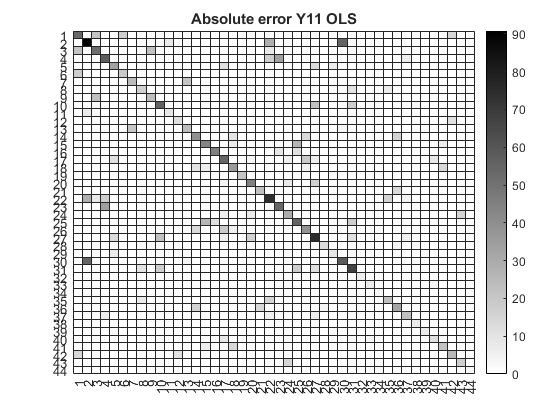

Froebius norm for Y22 OLS is 49.4074
Max norm for Y22 OLS is 32.8101


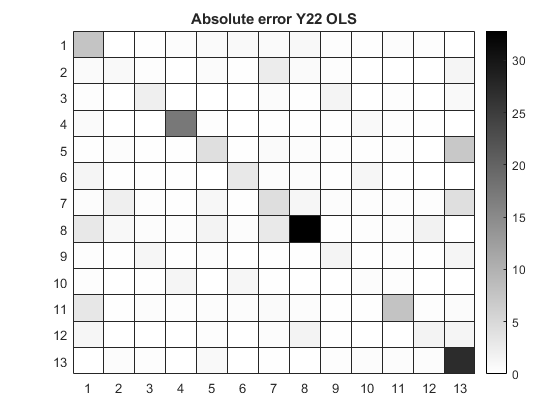

Froebius norm for OLS is 318.5426
Max norm for OLS is 90.7722


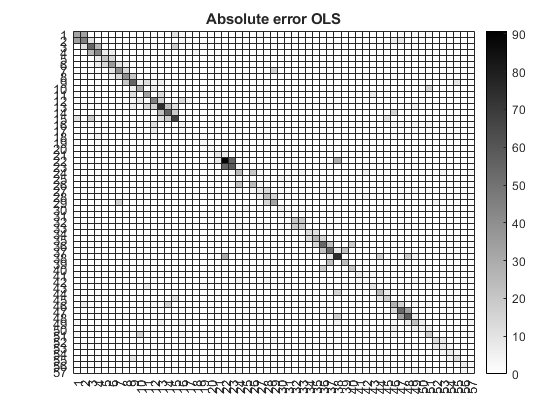

r = 16

Froebius norm for Y11 OLS is 301.5918
Max norm for Y11 OLS is 90.7722


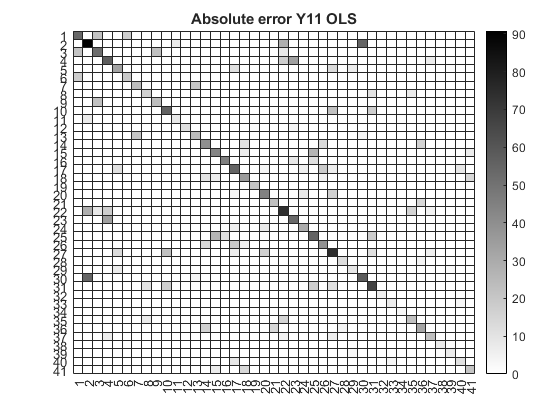

Froebius norm for Y22 OLS is 53.8411
Max norm for Y22 OLS is 32.9548


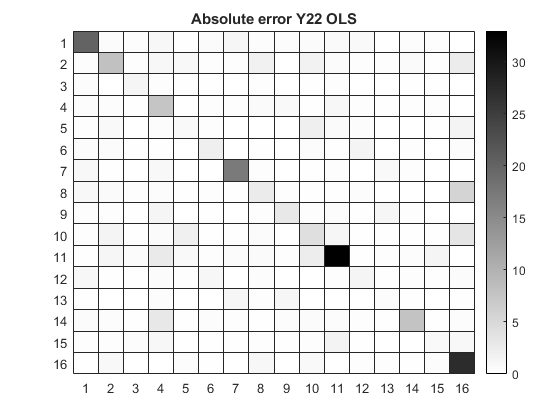

Froebius norm for OLS is 318.4144
Max norm for OLS is 90.7722


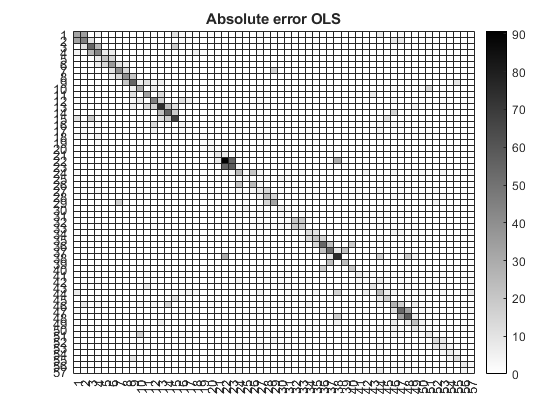

r = 19

Froebius norm for Y11 OLS is 299.368
Max norm for Y11 OLS is 90.7722


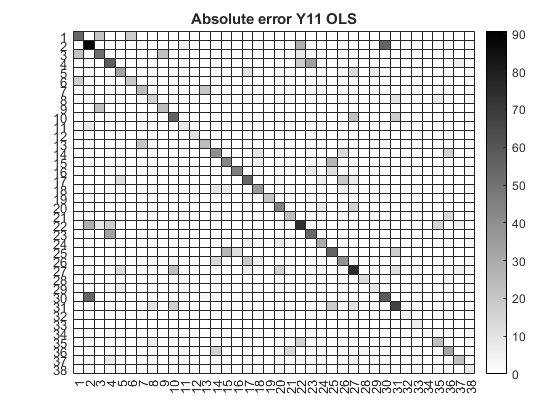

Froebius norm for Y22 OLS is 55.4229
Max norm for Y22 OLS is 32.2715


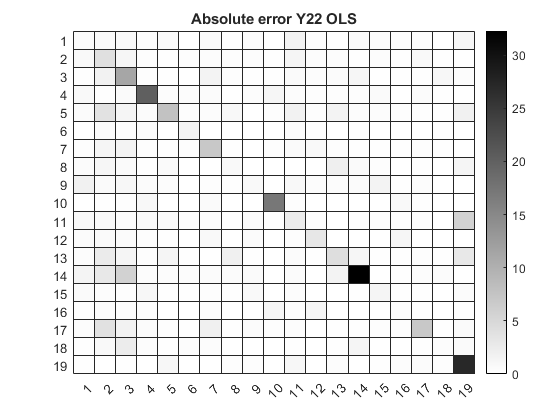

Froebius norm for OLS is 326.3631
Max norm for OLS is 90.7722


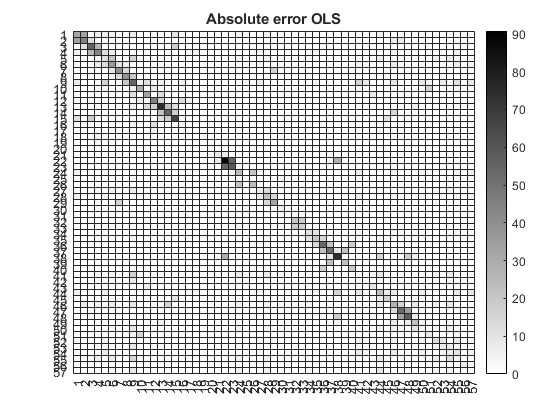

r = 22

Froebius norm for Y11 OLS is 294.959
Max norm for Y11 OLS is 90.7722


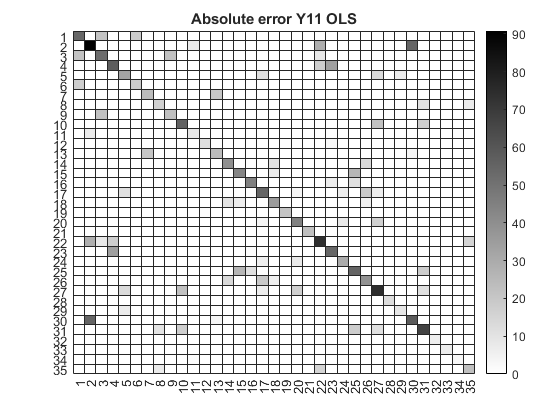

Froebius norm for Y22 OLS is 60.6306
Max norm for Y22 OLS is 32.2571


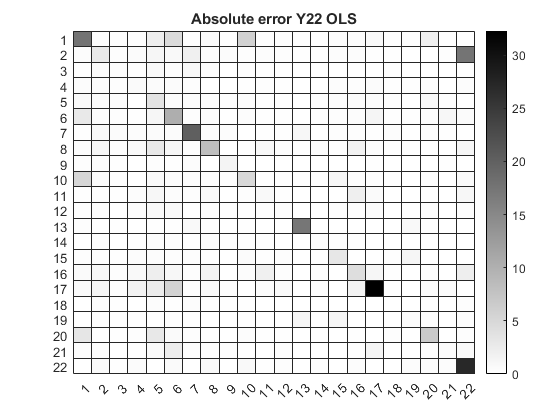

Froebius norm for OLS is 365.5865
Max norm for OLS is 90.7722


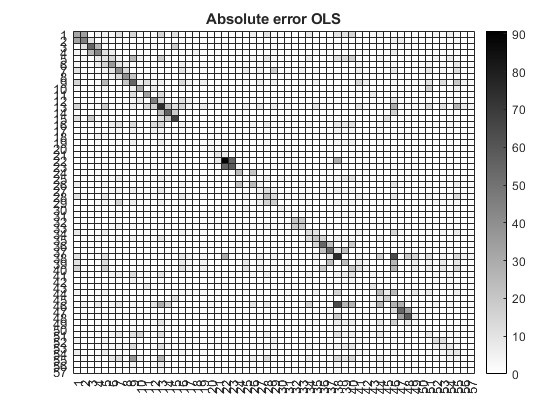

r = 25

Froebius norm for Y11 OLS is 293.1118
Max norm for Y11 OLS is 90.7722


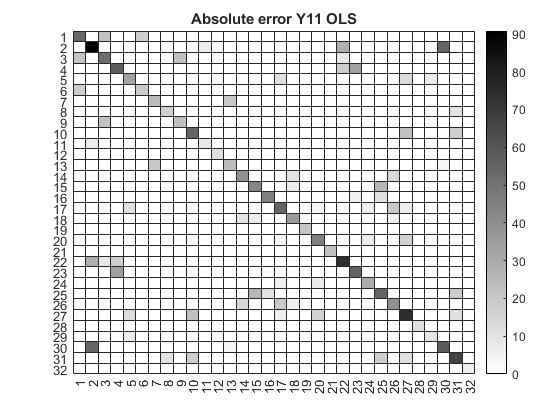

Froebius norm for Y22 OLS is 61.7032
Max norm for Y22 OLS is 32.1576


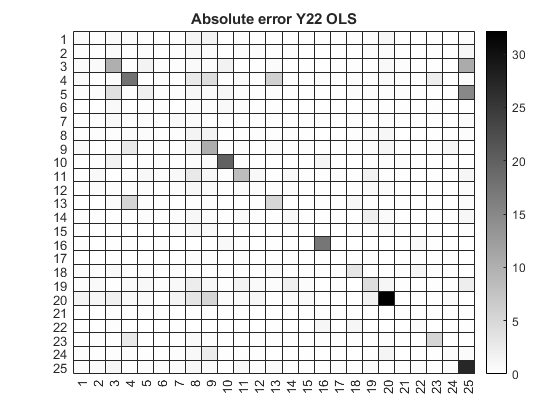

Froebius norm for OLS is 556.0634
Max norm for OLS is 106.3976


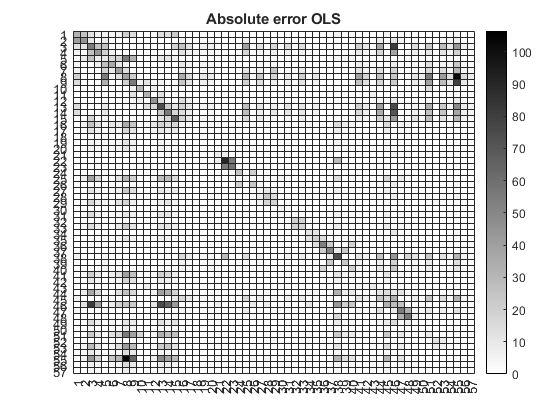

r = 28

Froebius norm for Y11 OLS is 265.3542
Max norm for Y11 OLS is 90.7722


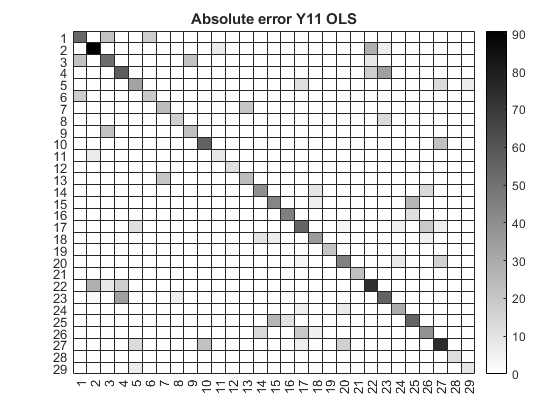

Froebius norm for Y22 OLS is 79.072
Max norm for Y22 OLS is 43.9206


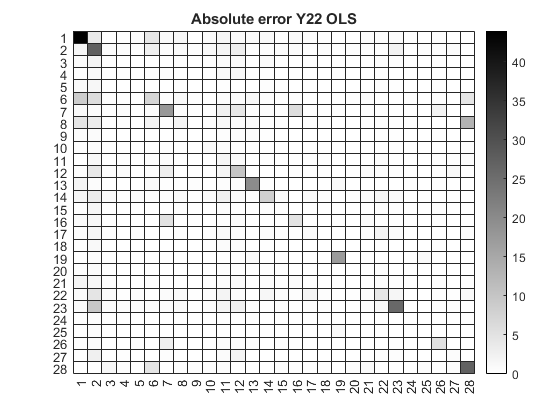

Froebius norm for OLS is 576485499333.3602
Max norm for OLS is 243877203095.9824


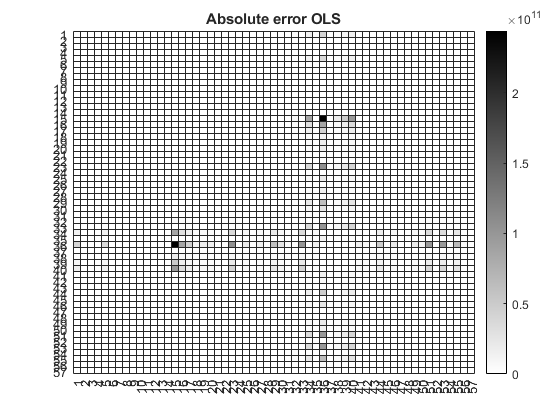

r = 30

Froebius norm for Y11 OLS is 264.701
Max norm for Y11 OLS is 90.7722


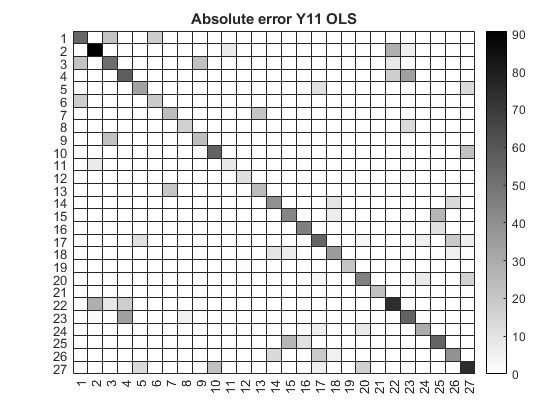

Froebius norm for Y22 OLS is 79.8236
Max norm for Y22 OLS is 44.3106


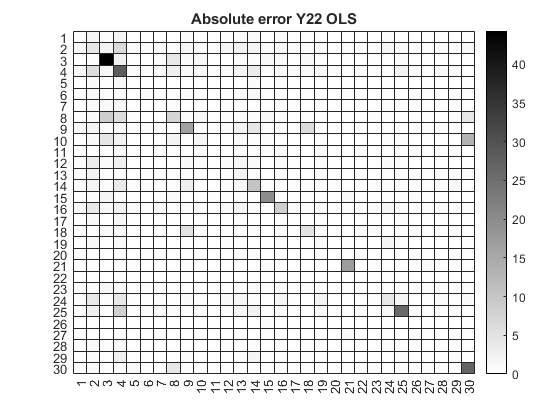

Froebius norm for OLS is 177998095211.6469
Max norm for OLS is 68530554894.3149


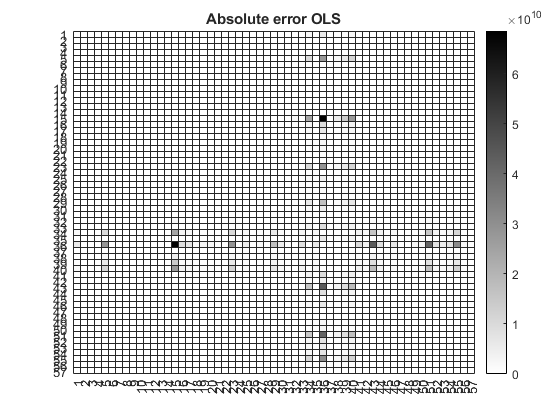

r = 33

Froebius norm for Y11 OLS is 235.1644
Max norm for Y11 OLS is 90.7722


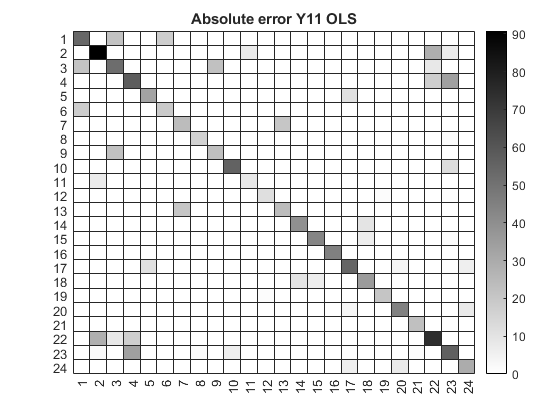

Froebius norm for Y22 OLS is 86.9835
Max norm for Y22 OLS is 44.5352


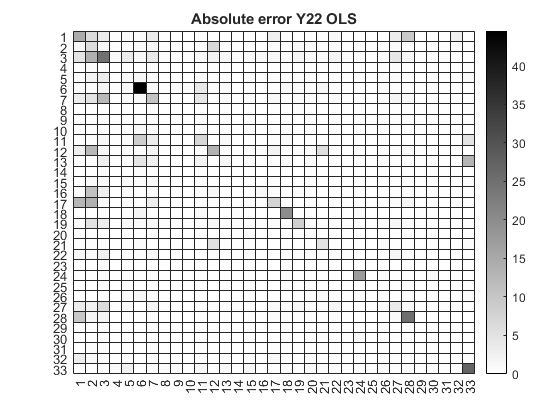

Froebius norm for OLS is 24834552130990.89
Max norm for OLS is 11336283842119.58


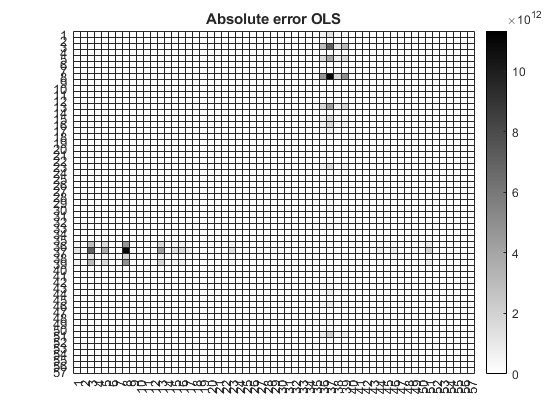

r = 36

Froebius norm for Y11 OLS is 244.2547
Max norm for Y11 OLS is 96.9656


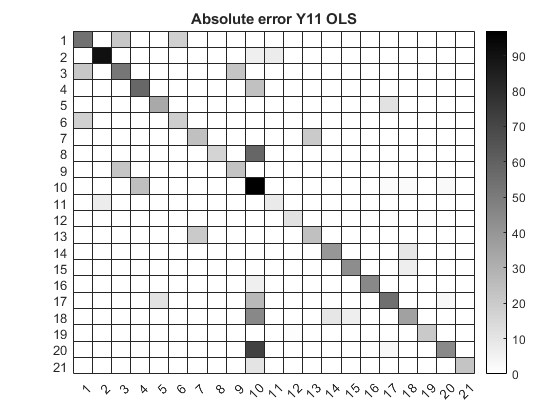

Froebius norm for Y22 OLS is 141.7433
Max norm for Y22 OLS is 53.2985


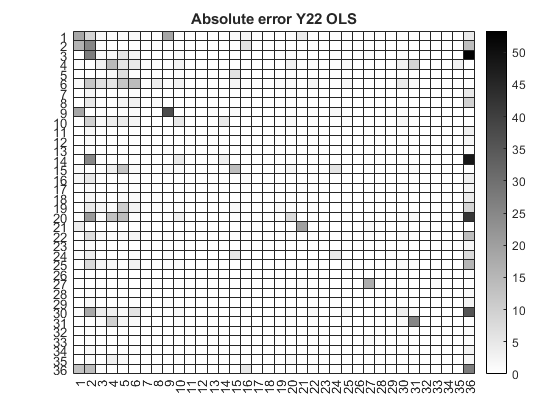

Froebius norm for OLS is 666132763468.4442
Max norm for OLS is 300836825897.4062


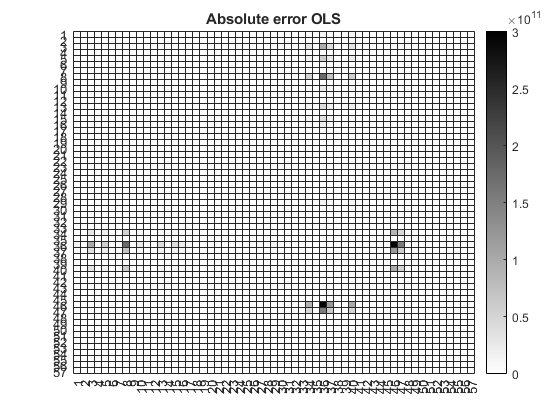

r = 39

Froebius norm for Y11 OLS is 222.4176
Max norm for Y11 OLS is 103.4608


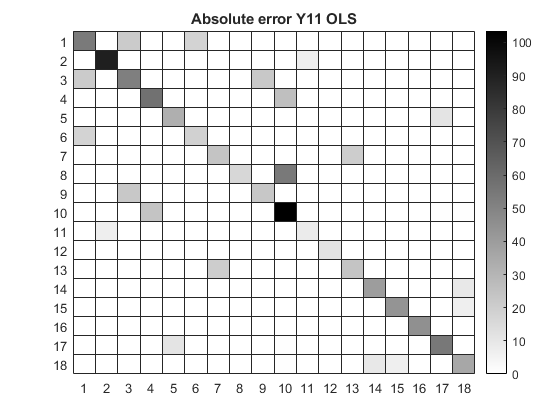

Froebius norm for Y22 OLS is 134.5096
Max norm for Y22 OLS is 75.3581


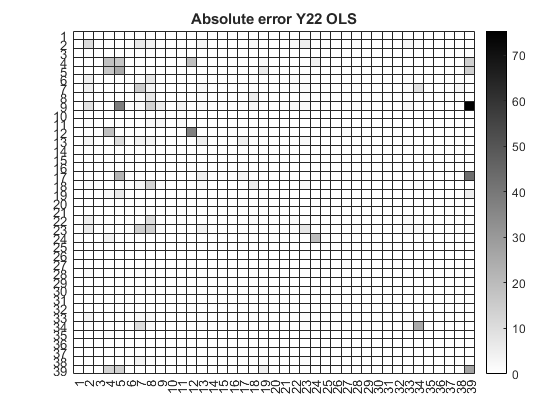

Froebius norm for OLS is 359.254
Max norm for OLS is 103.4608


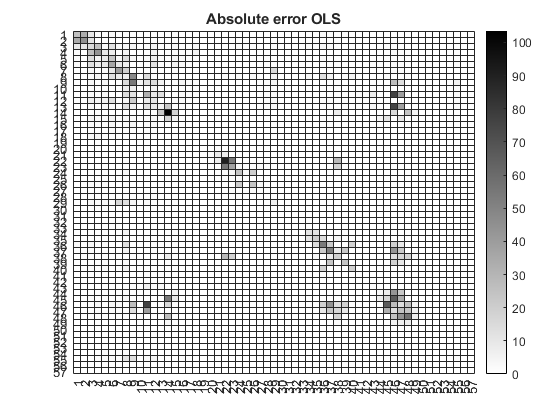

r = 42

Froebius norm for Y11 OLS is 231.7578
Max norm for Y11 OLS is 105.3518


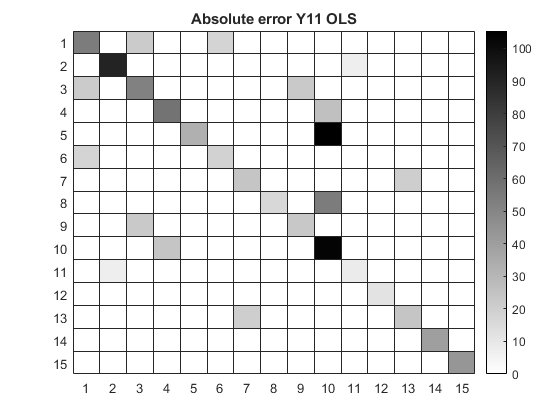

Froebius norm for Y22 OLS is 128.213
Max norm for Y22 OLS is 65.4465


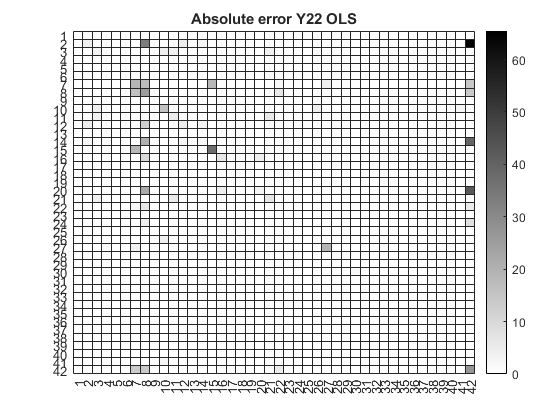

Froebius norm for OLS is 396.8948
Max norm for OLS is 143.394


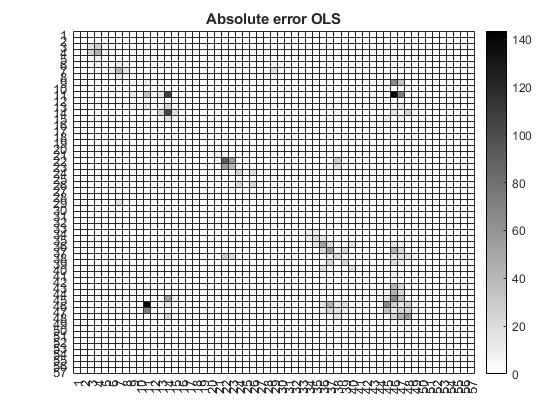

r = 45

Froebius norm for Y11 OLS is 221.0198
Max norm for Y11 OLS is 105.3518


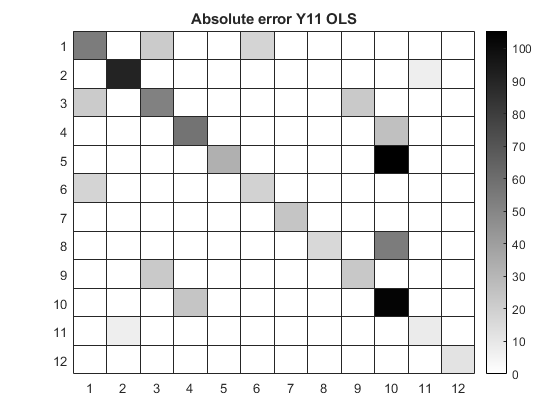

Froebius norm for Y22 OLS is 160.215
Max norm for Y22 OLS is 65.4465


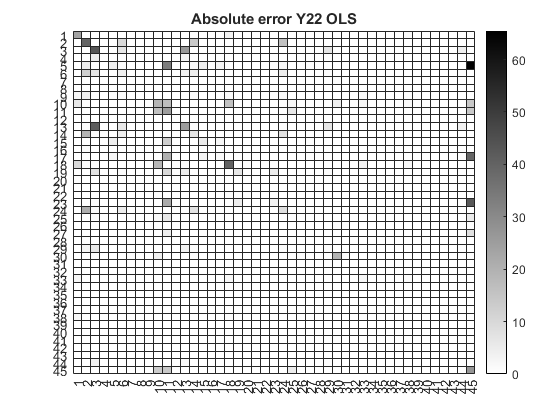

Froebius norm for OLS is 400.0437
Max norm for OLS is 143.394


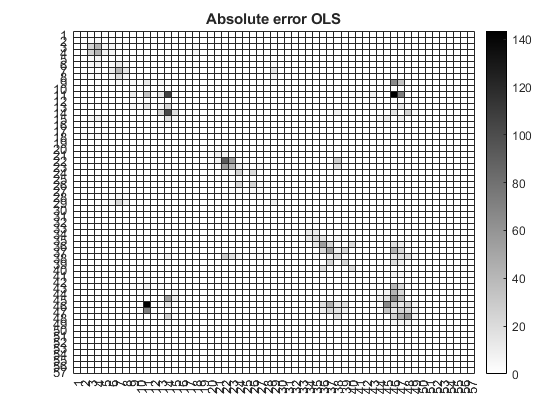

r = 48

Froebius norm for Y11 OLS is 150.112
Max norm for Y11 OLS is 90.7722


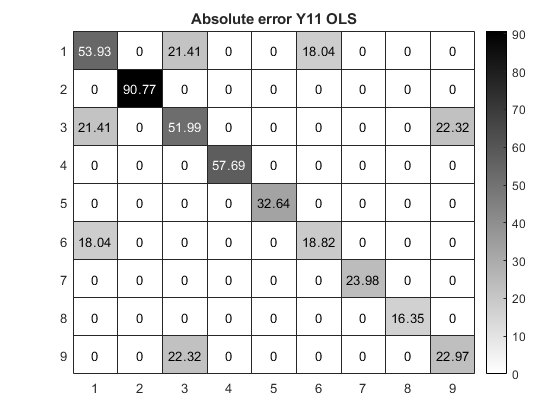

Froebius norm for Y22 OLS is 114.8996
Max norm for Y22 OLS is 41.3259


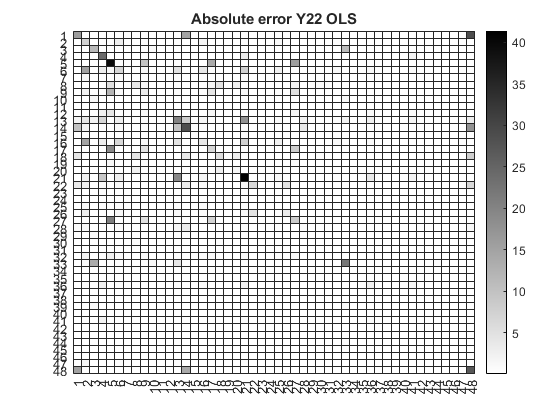

Froebius norm for OLS is 221.1761
Max norm for OLS is 90.7722


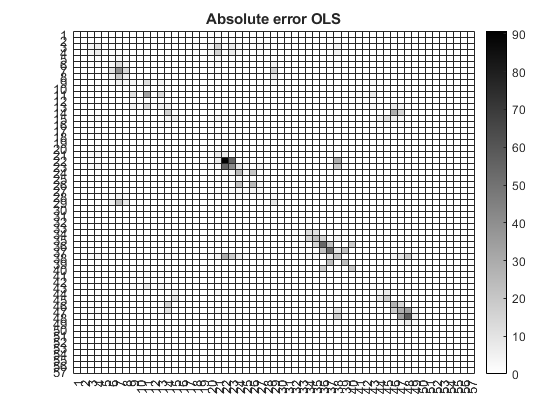

r = 51

Froebius norm for Y11 OLS is 142.0126
Max norm for Y11 OLS is 90.7722


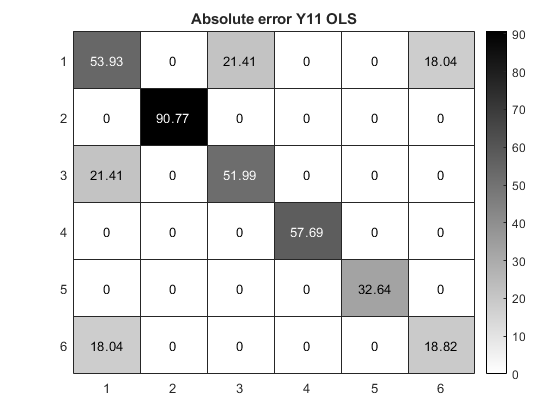

Froebius norm for Y22 OLS is 135.4887
Max norm for Y22 OLS is 42.3259


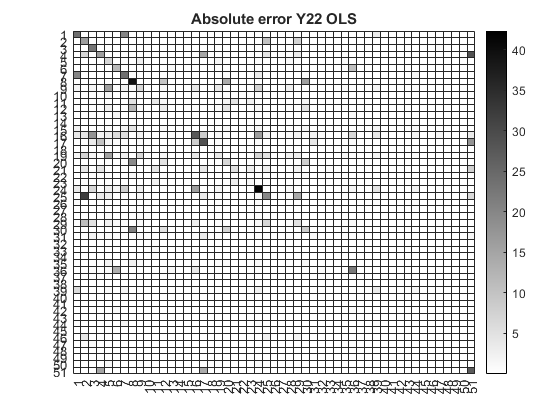

Froebius norm for OLS is 227.0557
Max norm for OLS is 90.7722


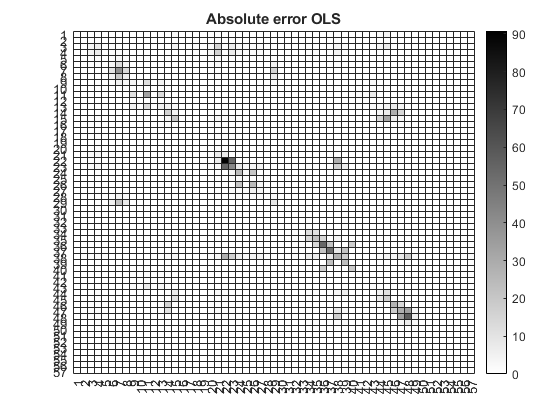

r = 54

Froebius norm for Y11 OLS is 121.5264
Max norm for Y11 OLS is 90.7722


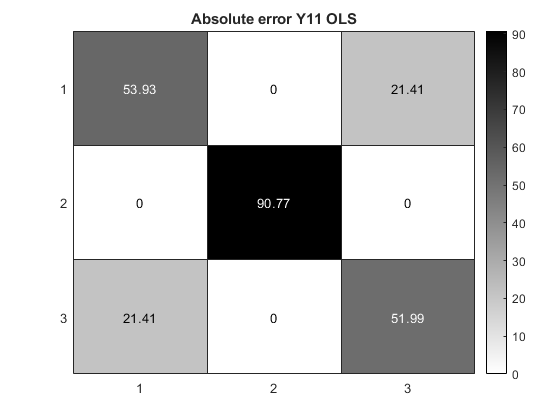

Froebius norm for Y22 OLS is 184.7288
Max norm for Y22 OLS is 57.6923


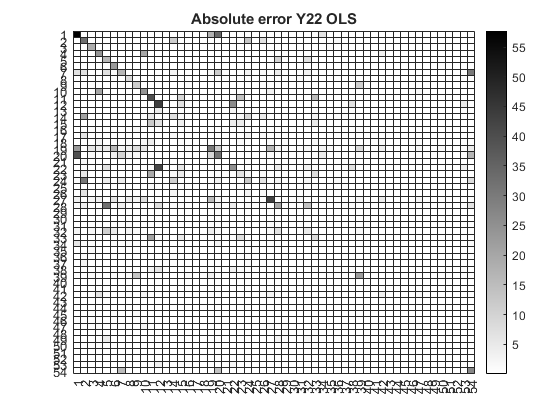

Froebius norm for OLS is 242.6915
Max norm for OLS is 90.7722


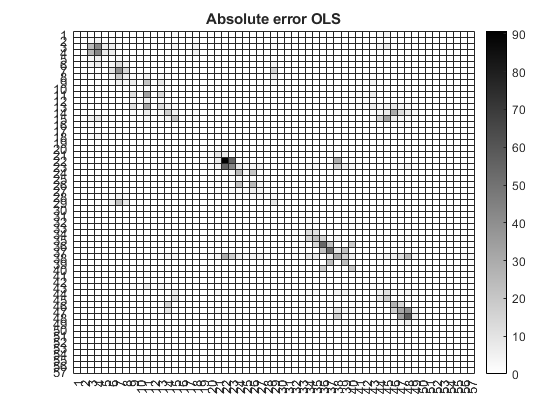

r = 57

Froebius norm for Y22 OLS is 245.5731
Max norm for Y22 OLS is 90.7722


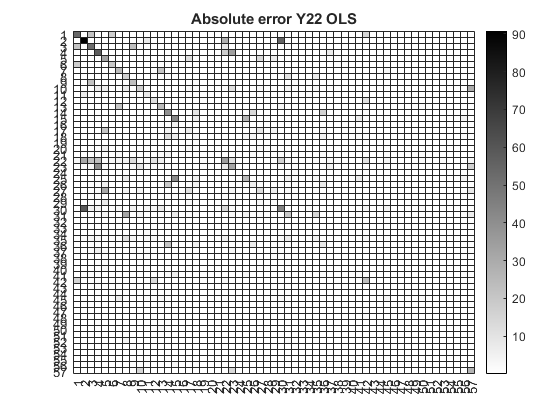

Froebius norm for OLS is 245.5731
Max norm for OLS is 90.7722


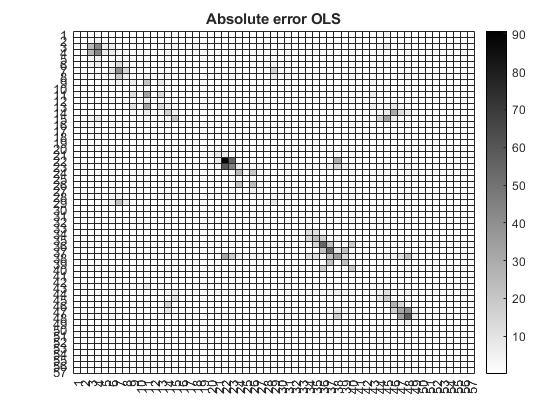

m = 	1.0e+12 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0288    0.0089    1.2417    0.0333    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


s = 	1.0e+12 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.1289    0.0398    5.5532    0.1490    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


benchmark = 	1.0e+13 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0416    0.0128    1.7901    0.0480    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


f_norms =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0    

Y11


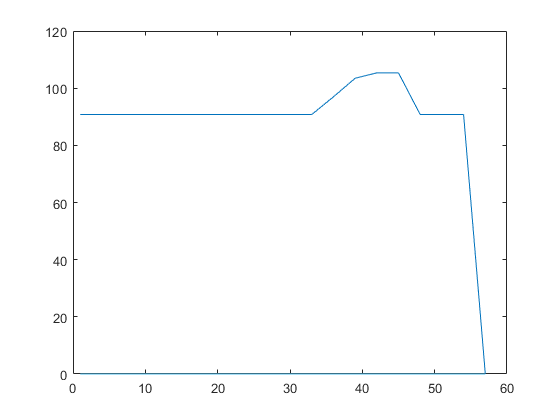

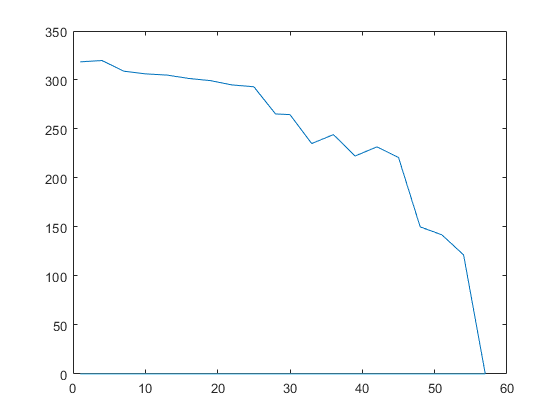

Y22


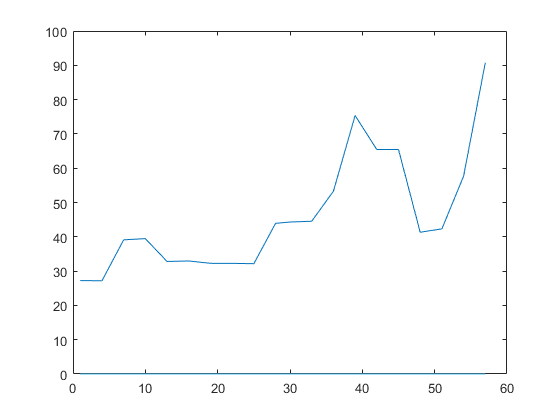

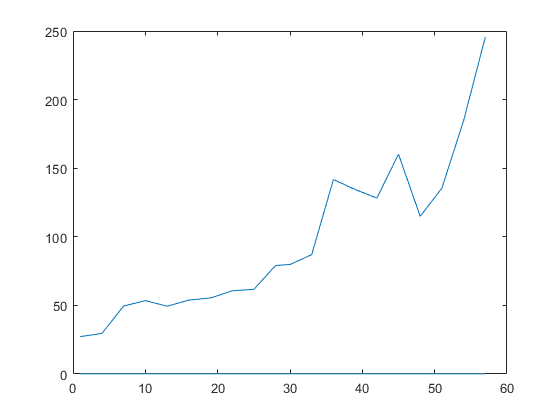

Y


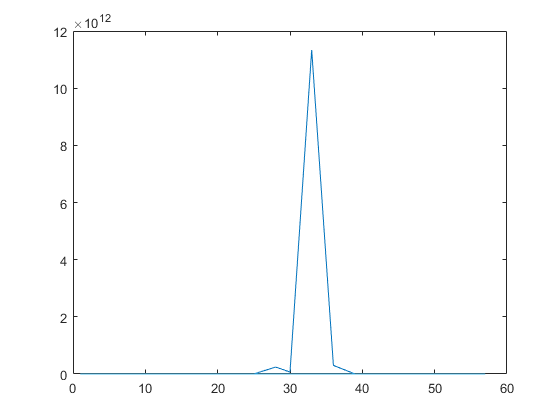

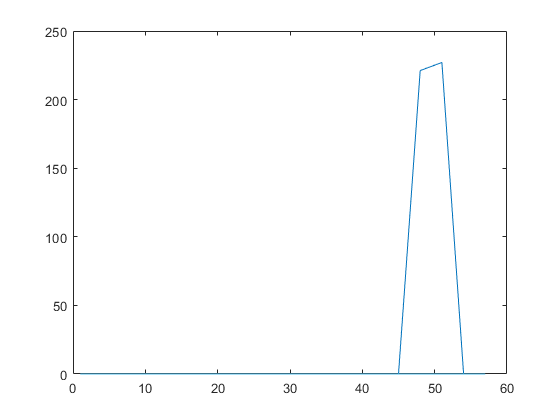

progressive(Y, n, bus_voltage, bus_current, 20)

function [] = progressive(y, n, v, i, n_points)
    ranks = round(linspace(1, n, n_points));
    max_norms = zeros(n_points);
    f_norms = zeros(n_points);
    y11_max_norms = zeros(n_points);
    y11_f_norms = zeros(n_points);
    y22_max_norms = zeros(n_points);
    y22_f_norms = zeros(n_points);
    [matlab_rank, T] = full_rank_partioning(v);
    partitioned_v = T*v;
    partitioned_i = T*i;
    matlab_rank
    
    for k = 1:n_points
        r = ranks(k)
        v1 = partitioned_v(1:end-r, :);
        v2 = partitioned_v(end-r+1:end, :);
        i1 = partitioned_i(1:end-r, :);
        i2 = partitioned_i(end-r+1:end, :);

        y11_size = n-r;
        y22_size = r;
        X = v1*pinv(v2);
        C = i2*pinv(v2) - pinv(v2)'*i1'*X;
        vec_c = reshape(C, [], 1);
        b = vec_c;
        A11 = -kron(X', X');
        A22 = eye(y22_size^2, y22_size^2);
        A12 = zeros(size(A11,1), size(A22,2));
        A = [A11 A22];
        x = A\b;
        
        x1 = x(1:y11_size^2);
        x2 = x(y11_size^2+1:end);
        
        Y11_hat = reshape(x1, [y11_size, y11_size]);
        Y22_hat = reshape(x2, [y22_size, y22_size]);
        Y12_hat = X'\(i2*pinv(v2)-Y22_hat);
        Y_hat = inv(T)*[Y11_hat, Y12_hat; Y12_hat', Y22_hat]*T;
        
        partitioned_Y = T*y*inv(T);
        y11 = partitioned_Y(1:y11_size, 1:y11_size);
        y22 = partitioned_Y(y11_size+1:end, y11_size+1:end);
        
        if r < n
            [y11_f_norms(k), y11_max_norms(k), ~] = error_metrics(y11, Y11_hat, 'Y11 OLS');
        end
        [y22_f_norms(k), y22_max_norms(k), ~] = error_metrics(y22, Y22_hat, 'Y22 OLS');
        [f_norms(k), max_norms(k), ~] = error_metrics(y, Y_hat, 'OLS');
        
        end
        
        m = mean(f_norms')
        s = std(f_norms')
        benchmark = m + 3*s
        f_norms(f_norms>benchmark) = 0
        
        disp("Y11");
        figure();
        plot(ranks, y11_max_norms);
        figure();
        plot(ranks, y11_f_norms);
        disp("Y22");
        figure();
        plot(ranks, y22_max_norms);
        figure();
        plot(ranks, y22_f_norms);
        disp("Y");
        figure();
        plot(ranks, max_norms);
        figure();
        plot(ranks, f_norms);
    end